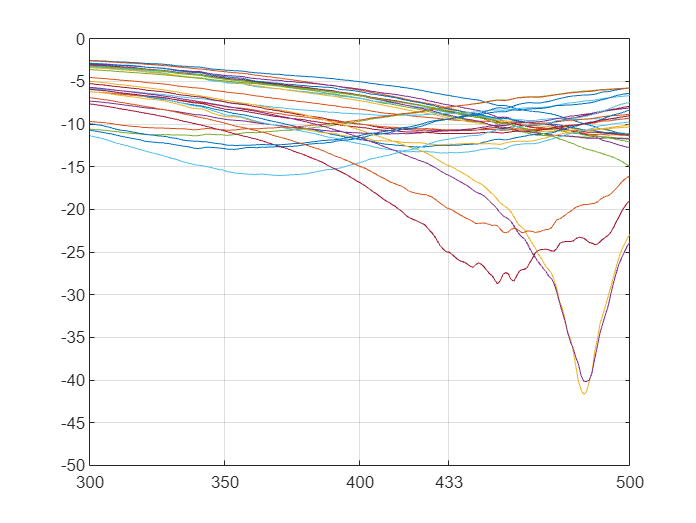

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Copper_Originals\Solder-porkandfat\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Copper_Originals\EPaint\";
%paste in your csv or xlsx files here:

FileNames = [
    "PF T1.xlsx";
    "PF T2.xlsx";
    "PF T3.xlsx";
    "PF T4.xlsx";
    "PF T5.xlsx";
    "PF T6.xlsx";
    "PF T7.xlsx";
    "PF T8.xlsx";
    "PF T9.xlsx";
    "PF T10.xlsx";
    "PF T11.xlsx";
    "PF T12.xlsx";
    "PF T13.xlsx";
    "PF T14.xlsx";
    "PF T15.xlsx";
    ];

FileCount = 1:15;

figure;
plotS11(DirectoryName, FileNames, FileCount);
hold on
plotS11(DirectoryName2, FileNames, FileCount);
hold off

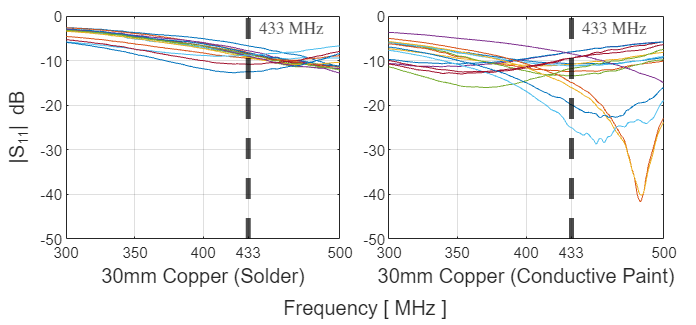



figure('Position', [1, 1, 750, 350])
t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
xlabel(t, " Frequency [ MHz ] ", 'FontSize', 12);
ylabel(t, " |S_{11}| {dB} ", "FontSize", 12);

% Tile 1
nexttile
plotS11(DirectoryName, FileNames, FileCount);
% hT1 = title('(a)', 'Position', [4 -65 0], 'FontSize', 11);
% xlabel(" (a) ", 'FontWeight', 'bold', 'FontSize', 12);
xlabel("30mm Copper (Solder)", 'FontSize', 12);
        xline(433, 'k--', ... % This is the LineSpec, the label comes next
        '433 MHz', ...
        'LineWidth', 3, ...
        'Interpreter', 'latex', ...
        'LabelOrientation', 'horizontal') %if you add text


%Tile 2
nexttile
plotS11(DirectoryName2, FileNames, FileCount);
% hT2 = title('(b)', 'Position', [4 -65 0], 'FontSize', 11);
% xlabel(" (b) ", 'FontWeight', 'bold', 'FontSize', 12);
xlabel("30mm Copper (Conductive Paint)", 'FontSize', 12);
        xline(433, 'k--', ... % This is the LineSpec, the label comes next
        '433 MHz', ...
        'LineWidth', 3, ...
        'Interpreter', 'latex', ...
        'LabelOrientation', 'horizontal') %if you add text

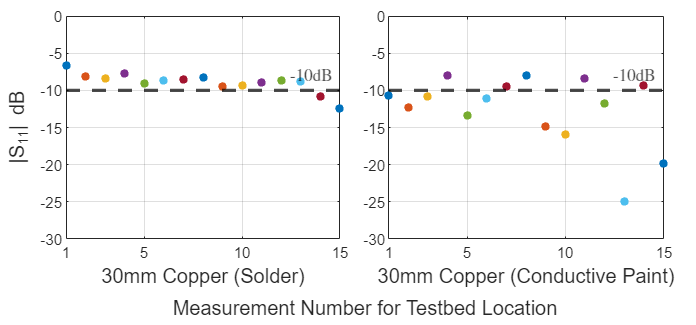



figure('Position', [1, 1, 750, 350])
t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
xlabel(t, " Measurement Number for Testbed Location ", 'FontSize', 12);
ylabel(t, " |S_{11}| {dB} ", "FontSize", 12);

% Tile 3
nexttile
plot433S11(DirectoryName, FileNames, FileCount);
xlabel("30mm Copper (Solder)", 'FontSize', 12);
yline(-10, 'k--', '-10dB', "LineWidth", 2, 'Interpreter', 'latex', 'LabelOrientation', 'horizontal');
% xlabel(" (c) ", 'FontWeight', 'bold', 'FontSize', 12);

% Tile 4
nexttile
plot433S11(DirectoryName2, FileNames, FileCount);
xlabel("30mm Copper (Conductive Paint)", 'FontSize', 12);
yline(-10, 'k--', '-10dB', "LineWidth", 2, 'Interpreter', 'latex', 'LabelOrientation', 'horizontal');

% xlabel(" (d) ", 'FontWeight', 'bold', 'FontSize', 12);



function plotS11(DirectoryName, FileNames, FileCount) %Just S11 plotting

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(:,1);
        MHz_PlotFreq = Freq/1e6;
        S11_dB = VNA_Zdata(:,2);
        plot(MHz_PlotFreq, S11_dB)
        % xlabel(" Frequency [ MHz ] ", 'FontSize', 11);
        % ylabel(" Magnitude { dB } ", "FontSize", 11);
        ylim([-50 0])            
        xticks([300 350 400 433 500])
        grid on;
        hold on;
    end
end

function plot433S11(DirectoryName, FileNames, FileCount) %S11 dB at 433 MHz

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        S11_dB = VNA_Zdata(134,2);
        plot(loopFiles,S11_dB, '.', 'MarkerSize', 15);
        ylim([-30 0])
        xticks([1 5 10 15])
        xlim([1 15])
        grid on;
        hold on;
    end
end